# Application Problems

## Problem 2.6 (First-order approximation of functions) 

### Part a)

syms x y
f1(x,y) = 2.*x + 3.*y + 1

$$f1(x, y) = 2\,x+3\,y+1$$

f2(x,y) = x.^2 + y.^2 - x.*y -5

$$f2(x, y) = x^{2}-x\,y+y^{2}-5$$

f3(x,y) = (x-5).*cos(y-5) - (y-5).*sin(x-5)

$$f3(x, y) = \cos\left(y-5\right)\,\left(x-5\right)-\sin\left(x-5\right)\,\left(y-5\right)$$

F1 = gradient(f1,[x,y])

$$F1(x, y) = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

F2 = gradient(f2,[x,y])

$$F2(x, y) = \left(\begin{array}{c} 2\,x-y\\ 2\,y-x \end{array}\right)$$

F3 = gradient(f3,[x,y])

$$F3(x, y) = \left(\begin{array}{c} \cos\left(y-5\right)-\cos\left(x-5\right)\,\left(y-5\right)\\ -\sin\left(x-5\right)-\sin\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

### Part b)

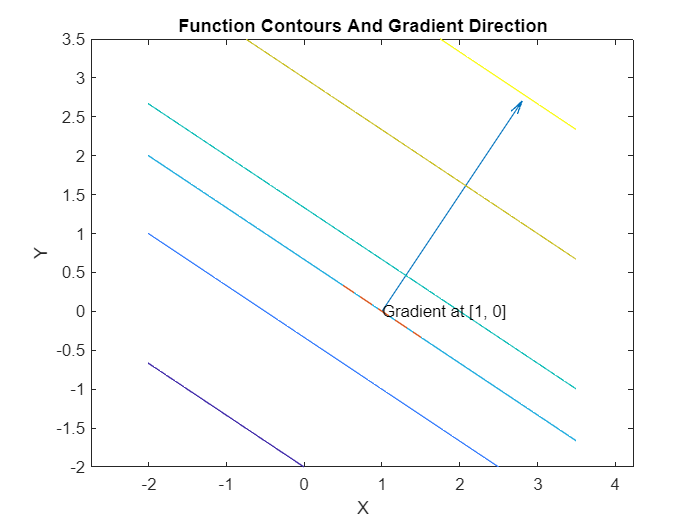

contourGradientPlot(f1,[1 0])

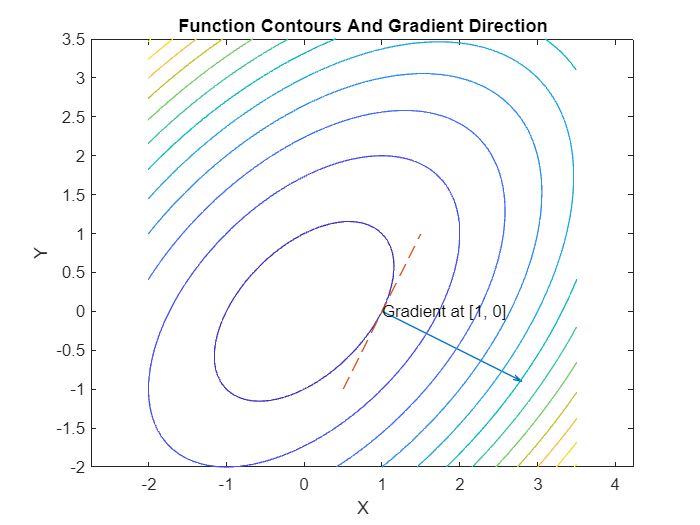

contourGradientPlot(f2,[1 0])

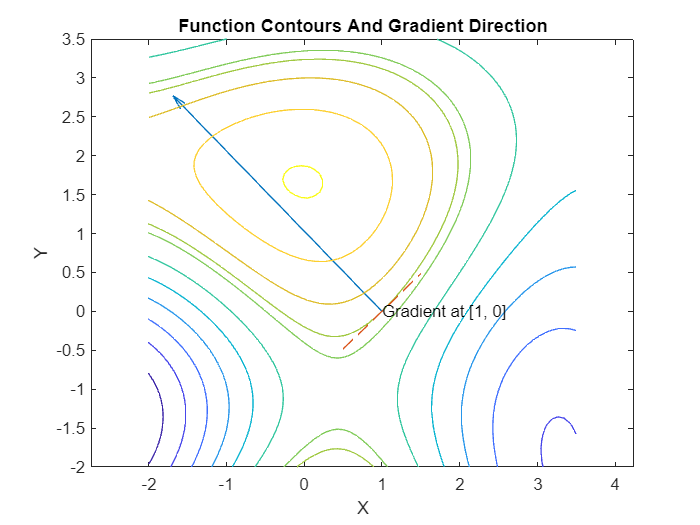

contourGradientPlot(f3,[1 0])

### Part c)

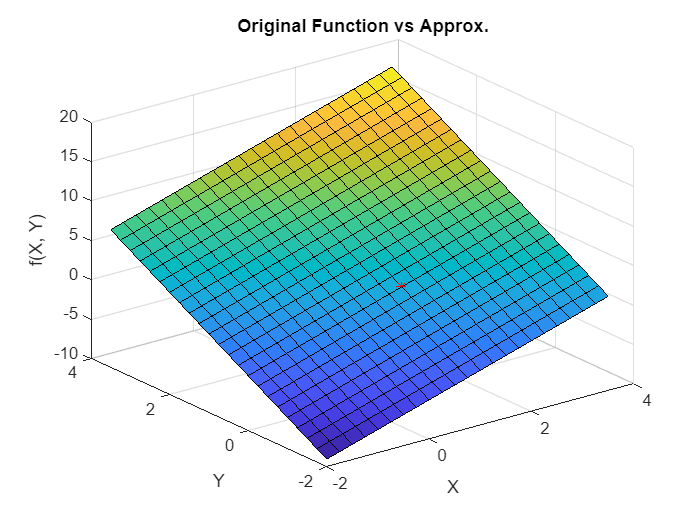

taylorMapp(f1, 2, [1 0])

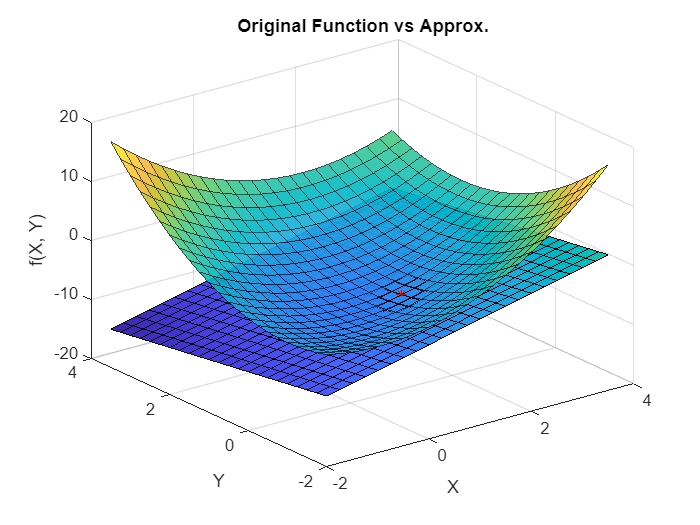

taylorMapp(f2, 2, [1 0])

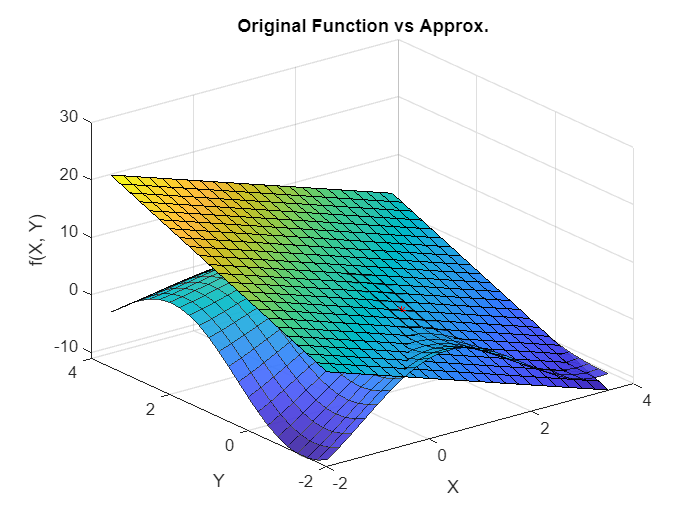

taylorMapp(f3, 2, [1 0])

## Problem 2.7 (Second-order approximation of functions)

### Part a) 

Ff1 = double(hessian(f1,[x,y]))

Ff1 =      0     0
     0     0


Ff2 = double(hessian(f2,[x,y]))

Ff2 =      2    -1
    -1     2


Ff3 = hessian(f3,[x,y])

$$Ff3(x, y) = \left(\begin{array}{cc} \sin\left(x-5\right)\,\left(y-5\right) & -\cos\left(x-5\right)-\sin\left(y-5\right)\\ -\cos\left(x-5\right)-\sin\left(y-5\right) & -\cos\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

### Part b)

[xx,yy] = meshgrid(-2:0.25:3.5);
a = 1;
b = 0;
z1 = taylor(f1,[x,y],[a b],'Order',3)

$$z1(x, y) = 2\,x+3\,y+1$$

z2 = taylor(f2,[x,y],[a b],'Order',3)

$$z2(x, y) = 2\,x-y+{\left(x-1\right)}^{2}-y\,\left(x-1\right)+y^{2}-6$$

z3 = taylor(f3,[x,y],[a b],'Order',3)

$$z3(x, y) = \frac{5\,\sin\left(4\right)\,{\left(x-1\right)}^{2}}{2}-5\,\sin\left(4\right)-4\,\cos\left(5\right)+y\,\left(\sin\left(4\right)-4\,\sin\left(5\right)\right)+2\,y^{2}\,\cos\left(5\right)+\left(5\,\cos\left(4\right)+\cos\left(5\right)\right)\,\left(x-1\right)-y\,\left(\cos\left(4\right)-\sin\left(5\right)\right)\,\left(x-1\right)$$

taylorMapp(f1, 2, [1 0])

taylorMapp(f2, 2, [1 0])

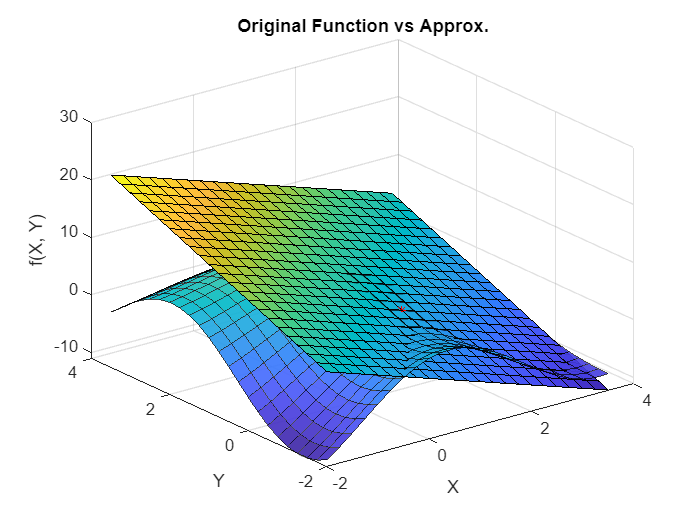

taylorMapp(f3, 2, [1 0])

### Part c)

#### Around (x, y) = (−0.7, 2)

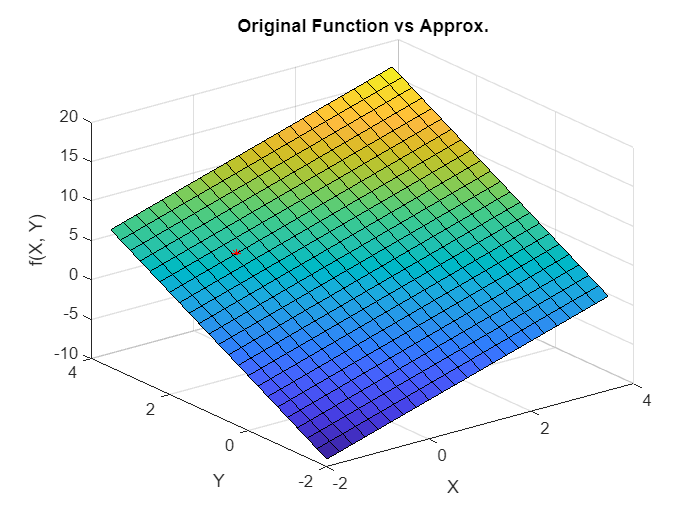

taylorMapp(f1, 3, [-0.7 2])

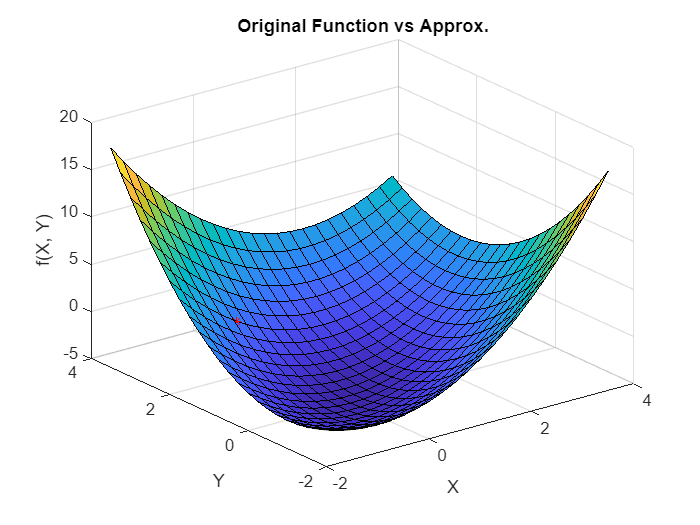

taylorMapp(f2, 3, [-0.7 2])

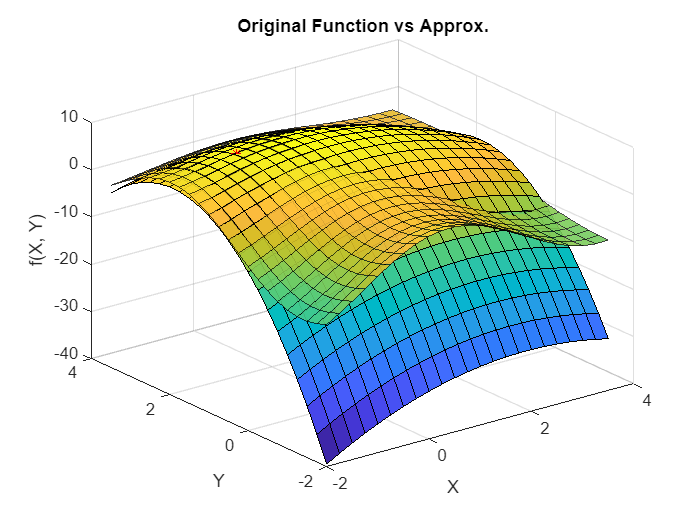

taylorMapp(f3, 3, [-0.7 2])

#### Around (x, y) = (2.5, -1)

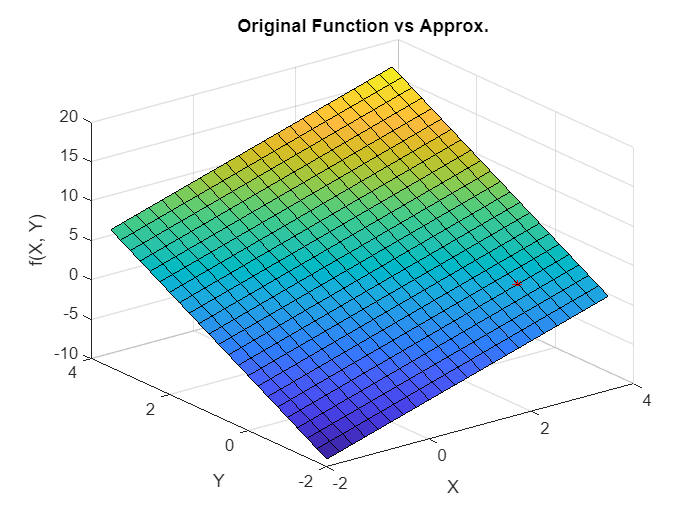

taylorMapp(f1, 3, [2.5 -1])

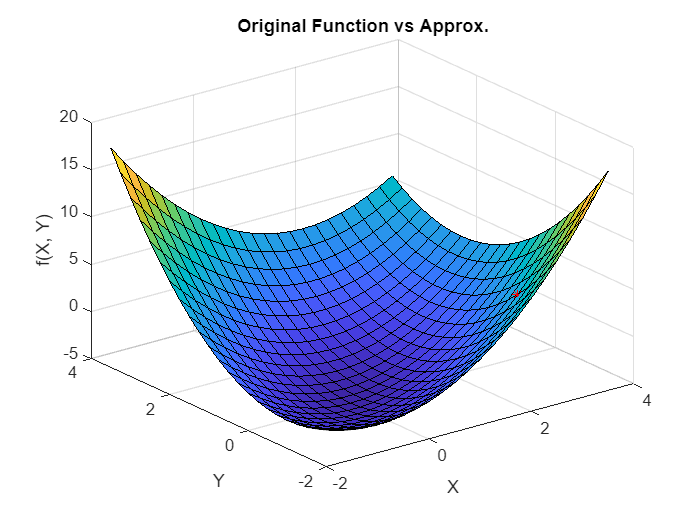

taylorMapp(f2, 3, [2.5 -1])

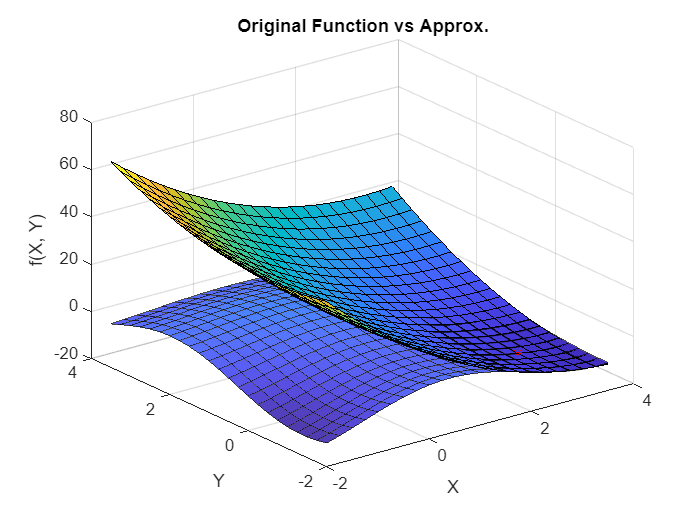

taylorMapp(f3, 3, [2.5 -1])

## Problem 2.8 (Google’s PageRank algorithm)

### Part a)

load 'pagerank_adj.mat'

A = J ./ sum(J);
[N,~] = size(A);
x = ones(N,1);
sum(A) % sum all columns

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


The sum of all columns of A are equal to 1.

### Part b)

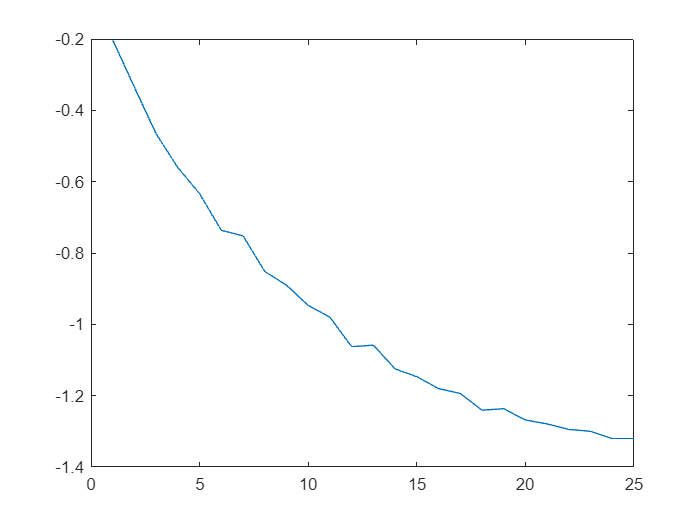

WorstScore =      0     0     0     0     0


WorstPage =      1     3     4     5    10


BestScore =     0.4101    0.3441    0.3215    0.3135    0.2851


BestPage =      2    35    36    58    49


k = 25;
e1 = powerIteration(A,k);

### Part c)

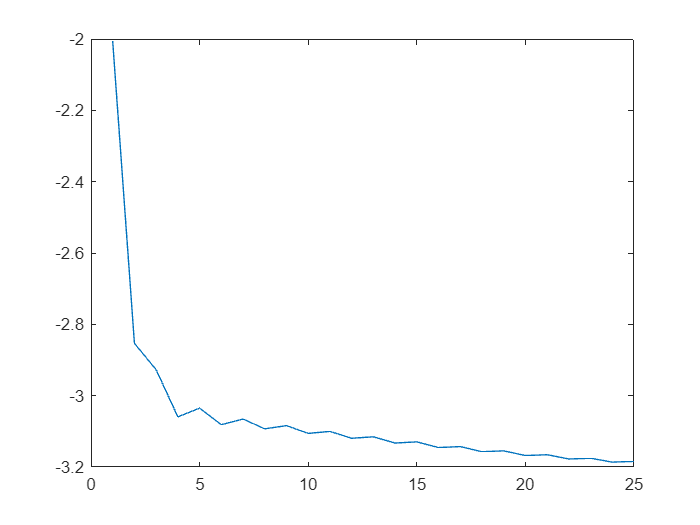

WorstScore =    -0.4796   -0.2401   -0.2401   -0.1800   -0.1355


WorstPage =    424   987   986   985   930


BestScore =     0.3034    0.2603    0.2432    0.2374    0.2157


BestPage =      2    35    36    58    49


e2 = shiftInvertPI(A,k,0.99);

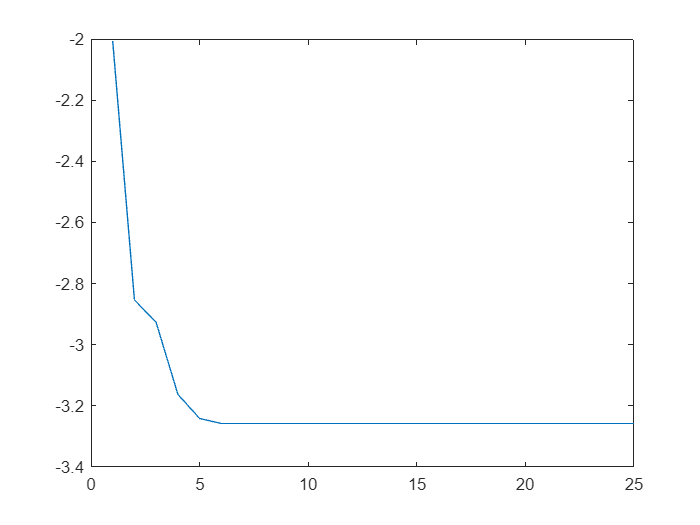

WorstScore =    -0.5458   -0.2732   -0.2732   -0.2048   -0.1536


WorstPage =    424   987   986   985   930


BestScore =     0.2576    0.2211    0.2065    0.2016    0.1831


BestPage =      2    35    36    58    49


e3 = rayleighQuotientI(A,k,0.99);

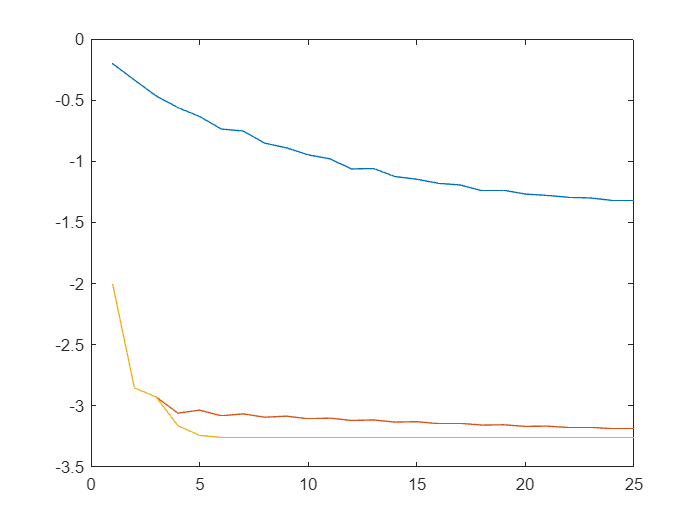

plot(1:k,log10(e1),1:k,log10(e2),1:k,log10(e3))

### Part d)

Based on the page rank scores, the order seems to be valid as the best ranked page is [http://www.hollins.edu/](http://www.hollins.edu/) which is the base URL for the entire University, it is intuitivly sound to excpect that most other websites within the university would link to the base URL. 

Adversly, while the normal power iteration formula isnt able to calculate the worst pages very accuretly the other two algorithms are in agreement regarding the least likely page being [http://www1.hollins.edu/homepages/hammerpw/qrhomepage.htm](http://www1.hollins.edu/homepages/hammerpw/qrhomepage.htm) which seems to be some sort of internal homepage related to a QR code. Therefore it is highly likely that it would recieve very few links from other pages. 

function error = powerIteration(A,k)
    [N,~] = size(A);
    x = zeros(N,k+1);
    x(:,1) = ones(N,1);
    error = zeros(1,k);
    error(1,1) = norm(A * x(:,1) - x(:,1));
    for i = 1:k
        y = A * x(:,i);
        x(:,i+1) = y / norm(y);
        error(:,i) = norm(A * x(:,i+1) - x(:,i+1));
    end
    figure;
    plot(1:k,log10(error))
    [B,I] = sort(x(:,k+1));
    WorstScore = B(1:5)'
    WorstPage = I(1:5)'
    B = flip(B);
    I = flip(I);
    BestScore = B(1:5)'
    BestPage = I(1:5)'
end
function error = shiftInvertPI(A,k,sigma)
    [N,~] = size(A);
    x = zeros(N,k+1);
    x(:,1) = ones(N,1);
    error = zeros(1,k);
    newA = (A - sigma*eye(N));
    for i = 1:k
        y = newA \ x(:,i);
        x(:,i+1) = y / norm(y);
        error(:,i) = norm(A * x(:,i+1) - x(:,i+1));
    end
    figure;
    plot(1:k,log10(error))
    [B,I] = sort(x(:,k+1));
    WorstScore = B(1:5)'
    WorstPage = I(1:5)'
    B = flip(B);
    I = flip(I);
    BestScore = B(1:5)'
    BestPage = I(1:5)'
end
function error = rayleighQuotientI(A,k,sigma)
    [N,~] = size(A);
    x = zeros(N,k+1);
    x(:,1) = ones(N,1);
    error = zeros(1,k);
    newA = (A - sigma*eye(N));
    for i = 1:3
        y = newA \ x(:,i);
        x(:,i+1) = y / norm(y);
        error(:,i) = norm(A * x(:,i+1) - x(:,i+1));
    end
    for i = 4:k
        sigmaK = (x(:,i)' * A * x(:,i))/( x(:,i)' * x(:,i) );
        y = (A - sigmaK*eye(N)) \ x(:,i);
        x(:,i+1) = y / norm(y);
        error(:,i) = norm(A * x(:,i+1) - x(:,i+1));
    end
    figure;
    plot(1:k,log10(error))
    [B,I] = sort(x(:,k+1));
    WorstScore = B(1:5)'
    WorstPage = I(1:5)'
    B = flip(B);
    I = flip(I);
    BestScore = B(1:5)'
    BestPage = I(1:5)'
end
function contourGradientPlot(f,position)
    syms x y    
    F = gradient(f,[x,y]);
    z = taylor(f,[x,y],position,'Order',2);
    apx(x) = solve(z,y);
    tangent(x) = solve(z,y) + position(2) - apx(position(1));
    uv = double(F(position(1),position(2)));
    quiver(position(1), position(2), uv(1),uv(2));
    hold on
    fcontour(f, [-2 3.5])
    fcontour(f,[-2 3.5],'LevelList',[double(f(position(1), position(2)))])
    plot([position(1)-0.5; position(1)+0.5], [double(tangent(position(1)-0.5));double(tangent(position(1)+0.5))],'--')
    text(position(1),position(2),"Gradient at [" + string(position(1)) + ", " + string(position(2)) + "]")
    axis equal
    xlabel('X');
    ylabel('Y');
    title('Function Contours And Gradient Direction');
    hold off
end 
function taylorMapp(f, order, position) 
    syms x y
    [xx,yy] = meshgrid(-2:0.25:3.5);
    z = taylor(f,[x,y],position,'Order',order);
    figure;
    surf(xx,yy,double(f(xx,yy)),'EdgeAlpha',0.7,'FaceAlpha',0.9)
    hold on
    surf(xx,yy,double(z(xx,yy)))
    plot3(position(1),position(2),double(f(position(1),position(2))),'r*')
    xlabel('X');
    ylabel('Y');
    zlabel('f(X, Y)');
    title('Original Function vs Approx.');
    hold off
end